clear all
close all
L=[2.5 1 1.5 2.5];
Q=[0.5 1 0.5];
[M01_ M1_1 M12 M23]=PositionMat(Q,L)

M01_ =     1.0000         0         0    2.1940
         0    1.0000         0         0
         0         0    1.0000   -1.1986
         0         0         0    1.0000


M1_1 =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


M12 =     0.7702   -0.5950    0.2298    1.1552
    0.5950    0.5403   -0.5950    0.8925
    0.2298    0.5950    0.7702    0.3448
         0         0         0    1.0000


M23 =     0.8776         0    0.4794    2.1940
         0    1.0000         0         0
   -0.4794         0    0.8776   -1.1986
         0         0         0    1.0000


M01=M01_*M1_1

M01 =     1.0000         0         0    3.1940
         0    1.0000         0         0
         0         0    1.0000   -1.1986
         0         0         0    1.0000


M02=M01*M12

M02 =     0.7702   -0.5950    0.2298    4.3492
    0.5950    0.5403   -0.5950    0.8925
    0.2298    0.5950    0.7702   -0.8538
         0         0         0    1.0000


M03=M02*M23

M03 =     0.5657   -0.5950    0.5709    5.7634
    0.8074    0.5403   -0.2369    2.9111
   -0.1675    0.5950    0.7861   -1.2726
         0         0         0    1.0000


M03*[0 0 0 1]'

ans =     5.7634
    2.9111
   -1.2726
    1.0000


DirectRobot(Q,L)

ans =     5.7634
    2.9111
   -1.2726
    1.0000


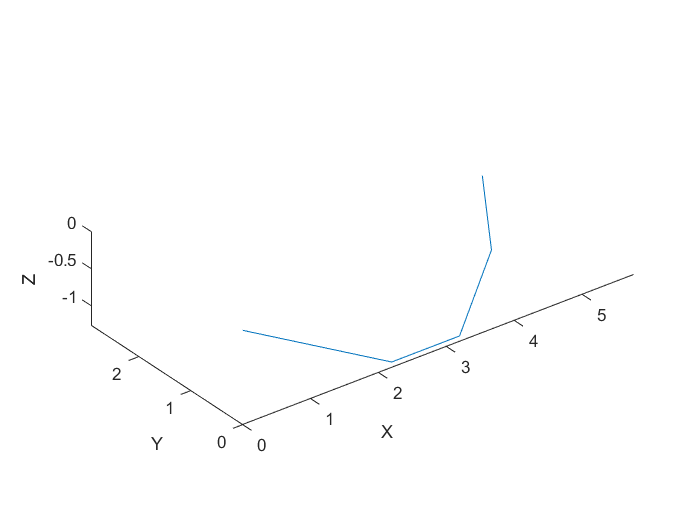

plotRobot(Q,L,1)

Q=(sym('q', [1 3]))

$$Q = \left(\begin{array}{ccc} q_{1} & q_{2} & q_{3} \end{array}\right)$$

L=(sym('l', [1 4]))

$$L = \left(\begin{array}{cccc} l_{1} & l_{2} & l_{3} & l_{4} \end{array}\right)$$

[M01_ M1_1 M12 M23]=PositionMat(Q,L)

$$M01\_ = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{1}\,\cos\left(q_{1}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$M1\_1 = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$M12 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{2} & \frac{1}{2}-\frac{\cos\left(q_{2}\right)}{2} & l_{3}\,\sigma_{1}\\ \sigma_{2} & \cos\left(q_{2}\right) & -\sigma_{2} & \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}\\ \frac{1}{2}-\frac{\cos\left(q_{2}\right)}{2} & \sigma_{2} & \sigma_{1} & -l_{3}\,\left(\frac{\cos\left(q_{2}\right)}{2}-\frac{1}{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{2}\right)}{2}+\frac{1}{2}\\ \sigma_{2}=\frac{\sqrt{2}\,\sin\left(q_{2}\right)}{2} \end{array}$$

$$M23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & 0 & \sin\left(q_{3}\right) & l_{4}\,\cos\left(q_{3}\right)\\ 0 & 1 & 0 & 0\\ -\sin\left(q_{3}\right) & 0 & \cos\left(q_{3}\right) & -l_{4}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M01=M01_*M1_1

$$M01 = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{2}+l_{1}\,\cos\left(q_{1}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M02=M01*M12

$$M02 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{2} & \frac{1}{2}-\frac{\cos\left(q_{2}\right)}{2} & l_{2}+l_{3}\,\sigma_{1}+l_{1}\,\cos\left(q_{1}\right)\\ \sigma_{2} & \cos\left(q_{2}\right) & -\sigma_{2} & \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}\\ \frac{1}{2}-\frac{\cos\left(q_{2}\right)}{2} & \sigma_{2} & \sigma_{1} & -l_{3}\,\left(\frac{\cos\left(q_{2}\right)}{2}-\frac{1}{2}\right)-l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{2}\right)}{2}+\frac{1}{2}\\ \sigma_{2}=\frac{\sqrt{2}\,\sin\left(q_{2}\right)}{2} \end{array}$$

M03=M02*M23

$$M03 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{3}\right)\,\sigma_{2}+\sin\left(q_{3}\right)\,\sigma_{1} & -\sigma_{5} & \sin\left(q_{3}\right)\,\sigma_{2}-\cos\left(q_{3}\right)\,\sigma_{1} & l_{2}+l_{3}\,\sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+l_{4}\,\cos\left(q_{3}\right)\,\sigma_{2}+l_{4}\,\sin\left(q_{3}\right)\,\sigma_{1}\\ \sigma_{4}+\sigma_{3} & \cos\left(q_{2}\right) & \sigma_{3}-\sigma_{4} & \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ -\cos\left(q_{3}\right)\,\sigma_{1}-\sin\left(q_{3}\right)\,\sigma_{2} & \sigma_{5} & \cos\left(q_{3}\right)\,\sigma_{2}-\sin\left(q_{3}\right)\,\sigma_{1} & -l_{3}\,\sigma_{1}-l_{1}\,\sin\left(q_{1}\right)-l_{4}\,\cos\left(q_{3}\right)\,\sigma_{1}-l_{4}\,\sin\left(q_{3}\right)\,\sigma_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{2}\right)}{2}-\frac{1}{2}\\ \sigma_{2}=\frac{\cos\left(q_{2}\right)}{2}+\frac{1}{2}\\ \sigma_{3}=\frac{\sqrt{2}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ \sigma_{4}=\frac{\sqrt{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{2}\\ \sigma_{5}=\frac{\sqrt{2}\,\sin\left(q_{2}\right)}{2} \end{array}$$

Dir=M03*[0 0 0 1]'

$$Dir = \begin{array}{l} \left(\begin{array}{c} l_{2}+l_{3}\,\sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+l_{4}\,\cos\left(q_{3}\right)\,\sigma_{2}+l_{4}\,\sin\left(q_{3}\right)\,\sigma_{1}\\ \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ -l_{3}\,\sigma_{1}-l_{1}\,\sin\left(q_{1}\right)-l_{4}\,\cos\left(q_{3}\right)\,\sigma_{1}-l_{4}\,\sin\left(q_{3}\right)\,\sigma_{2}\\ 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{2}\right)}{2}-\frac{1}{2}\\ \sigma_{2}=\frac{\cos\left(q_{2}\right)}{2}+\frac{1}{2} \end{array}$$

J=jacobian(Dir,Q)

$$J = \begin{array}{l} \left(\begin{array}{ccc} -l_{1}\,\sin\left(q_{1}\right) & -\sigma_{5}-\sigma_{2}-\sigma_{1} & l_{4}\,\cos\left(q_{3}\right)\,\sigma_{3}-l_{4}\,\sin\left(q_{3}\right)\,\sigma_{4}\\ 0 & \frac{\sqrt{2}\,l_{3}\,\cos\left(q_{2}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2} & \frac{\sqrt{2}\,l_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{2}-\frac{\sqrt{2}\,l_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ -l_{1}\,\cos\left(q_{1}\right) & \sigma_{5}+\sigma_{2}+\sigma_{1} & l_{4}\,\sin\left(q_{3}\right)\,\sigma_{3}-l_{4}\,\cos\left(q_{3}\right)\,\sigma_{4}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ \sigma_{2}=\frac{l_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{2}\\ \sigma_{3}=\frac{\cos\left(q_{2}\right)}{2}-\frac{1}{2}\\ \sigma_{4}=\frac{\cos\left(q_{2}\right)}{2}+\frac{1}{2}\\ \sigma_{5}=\frac{l_{3}\,\sin\left(q_{2}\right)}{2} \end{array}$$